clear all
clc

% Homework 2 - Problem 1 case x1-x2
% Student Name: Giuditta Sigona
% Created on 16/04/2022
% Last version xx/yy/zz

% matlab colors
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

s = tf('s');
om = logspace(-2,5,1000);
t = 0:0.001:10;

% Parameters
m1=1000;
m2=10;
k=0.001; 
B=0.5;

%systems
x1 = (m2*s^2+B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1));
x2 = (B*s-k)/((s^2)*(m1*m2*s^2+B*(m1+m2)*s-k*m1));
diff = m2/(m1*m2*s^2+B*(m1+m2)*s-k*m1)

diff =
 
           10
  ---------------------
  10000 s^2 + 505 s - 1
 
Continuous-time transfer function.




% ************* case x1-x2 *******************

zpk(diff)   % factorized into the zero-pole-gain form

ans =
 
           0.001
  ------------------------
  (s+0.05241) (s-0.001908)
 
Continuous-time zero/pole/gain model.




% Sensitivity Bode plot
Cont = pidtune(diff,'pid');

Loop=loopsens(diff,Cont);
Loop.Stable

ans = 1

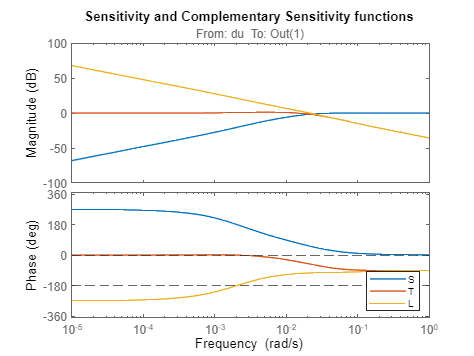


figure(1)
bode(Loop.Si,Loop.Ti,Loop.Li)
yline(0,'--')
yline(-180,'--')
legA = legend('S','T','L','Location','SouthEast');
set(legA,'FontSize',8)
title('Sensitivity and Complementary Sensitivity functions')


% Find alpha
syms a b c d alpha s 

numP =(1/m1);
denP = (s^2 + B*((m1+m2)/(m1*m2))*s - k/m2); 
P = numP/denP

$$P = \frac{1}{1000\,\left(s^{2}+\frac{101\,s}{2000}-\frac{1}{10000}\right)}$$


numC =(a*s + b);
denC = (s^2 + c*s + d);
C = numC/denC  % Proper controller 

$$C = \frac{b+a\,s}{s^{2}+c\,s+d}$$


p_s= numC*numP + denC*denP;
p_s=vpa(collect(p_s))

$$p\_s = s^{4}+\left(c+0.0505\right)\,s^{3}+\left(0.0505\,c+d-0.0001\right)\,s^{2}+\left(0.001\,a-0.0001\,c+0.0505\,d\right)\,s+0.001\,b-0.0001\,d$$


p_star=(s+alpha*(1+j))^2*(s+alpha*(1-j))^2;   % p*(s)
p_star=collect(p_star)

$$p\_star = s^{4}+\left(4\,\alpha \right)\,s^{3}+\left(8\,\alpha^{2}\right)\,s^{2}+\left(8\,\alpha^{3}\right)\,s+4\,\alpha^{4}$$


c = vpa(solve(c+0.0505 == 4*alpha, c))

$$c = 4.0\,\alpha -0.0505$$

d = vpa(solve(0.0505*c + d - 0.0001 ==8*alpha^2, d))

$$d = 8.0\,\alpha^{2}-0.202\,\alpha +0.00265025$$

a = vpa(solve(0.001*a - 0.0001*c + 0.0505*d == 8*alpha^3 , a))

$$a = 8000.0\,\alpha^{3}-404.0\,\alpha^{2}+10.601\,\alpha -0.138887625$$

b = vpa(solve(0.001*b - 0.0001*d == 4*alpha^4, b))

$$b = 4000.0\,\alpha^{4}+0.8\,\alpha^{2}-0.0202\,\alpha +0.000265025$$


% pick alpha >= 0.026
s = tf('s');
alpha1 = 0.026;

a1 = eval(subs(a,alpha,alpha1));  % eval convert symbol to value
b1 = eval(subs(b,alpha,alpha1));
c1 = eval(subs(c,alpha,alpha1));
d1 = eval(subs(d,alpha,alpha1));

C1= (a1*s + b1)/(s^2 + c1*s + d1)

C1 =
 
    0.004242 s + 0.002109
  -------------------------
  s^2 + 0.0535 s + 0.002806
 
Continuous-time transfer function.



L1=loopsens(diff,C1)

L1 = struct with fields:
        Si: [1×1 ss]
        Ti: [1×1 ss]
        Li: [1×1 tf]
        So: [1×1 ss]
        To: [1×1 ss]
        Lo: [1×1 tf]
       PSi: [1×1 ss]
       CSo: [1×1 ss]
     Poles: [4×1 double]
    Stable: 1


% poli = L1.Poles
Stabilita = L1.Stable

Stabilita = 1


%**************
alpha2 = 0.1;

a2 = eval(subs(a,alpha,alpha2));  % eval convert symbol to value
b2 = eval(subs(b,alpha,alpha2));
c2 = eval(subs(c,alpha,alpha2));
d2 = eval(subs(d,alpha,alpha2));

C2= (a2*s + b2)/(s^2 + c2*s + d2)

C2 =
 
      4.881 s + 0.4062
  ------------------------
  s^2 + 0.3495 s + 0.06245
 
Continuous-time transfer function.



L2=loopsens(diff,C2);
L2.Stable

ans = 1


%**************

alpha3 = 1;

a3 = eval(subs(a,alpha,alpha3));  % eval convert symbol to value
b3 = eval(subs(b,alpha,alpha3));
c3 = eval(subs(c,alpha,alpha3));
d3 = eval(subs(d,alpha,alpha3));

C3= (a3*s + b3)/(s^2 + c3*s + d3)

C3 =
 
     7606 s + 4001
  --------------------
  s^2 + 3.95 s + 7.801
 
Continuous-time transfer function.



L3=loopsens(diff,C3);
L2.Stable

ans = 1


%*************
alpha4 = 10;

a4 = eval(subs(a,alpha,alpha4));  % eval convert symbol to value
b4 = eval(subs(b,alpha,alpha4));
c4 = eval(subs(c,alpha,alpha4));
d4 = eval(subs(d,alpha,alpha4));

C4= (a4*s + b4)/(s^2 + c4*s + d4)

C4 =
 
   7.96e06 s + 4e07
  -------------------
  s^2 + 39.95 s + 798
 
Continuous-time transfer function.



L4=loopsens(diff,C4);
L4.Stable

ans = 1


%**************
alpha5 = 50;

a5 = eval(subs(a,alpha,alpha5));  % eval convert symbol to value
b5 = eval(subs(b,alpha,alpha5));
c5 = eval(subs(c,alpha,alpha5));
d5 = eval(subs(d,alpha,alpha5));

C5= (a5*s + b5)/(s^2 + c5*s + d5)

C5 =
 
     9.99e08 s + 2.5e10
  ------------------------
  s^2 + 199.9 s + 1.999e04
 
Continuous-time transfer function.



L5=loopsens(diff,C5);
L5.Stable

ans = 1

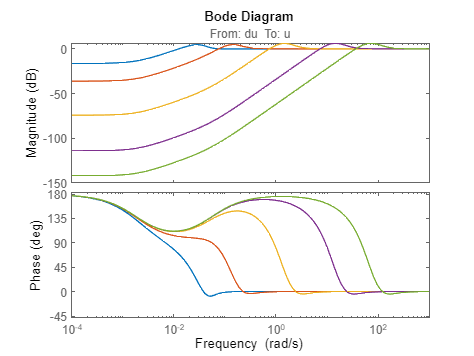



bode(L1.Si,L2.Si,L3.Si,L4.Si,L5.Si)

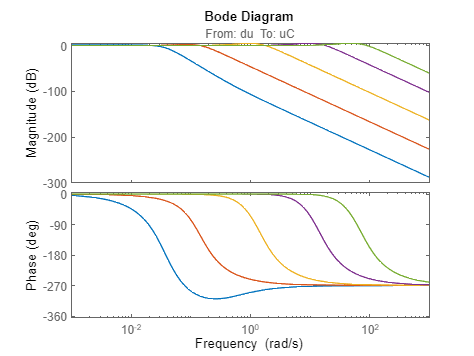

bode(L1.Ti,L2.Ti,L3.Ti,L4.Ti,L5.Ti)

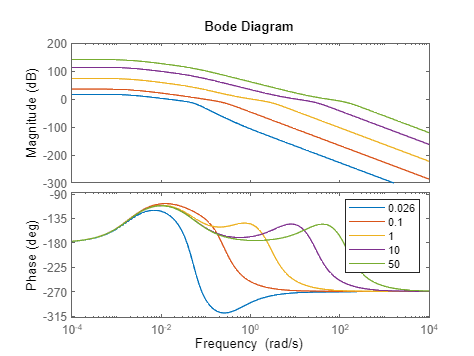

bode(L1.Li,L2.Li,L3.Li,L4.Li,L5.Li)
legend('0.026','0.1','1','10','50')

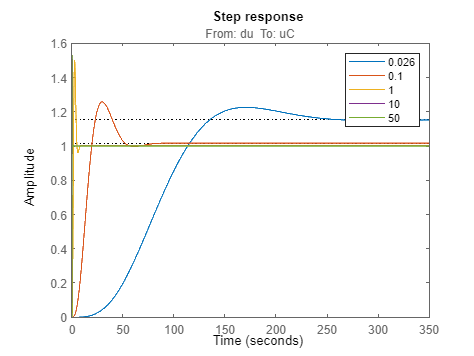



step(L1.Ti,L2.Ti,L3.Ti,L4.Ti,L5.Ti)
legend('0.026','0.1','1','10','50')
title('Step response')